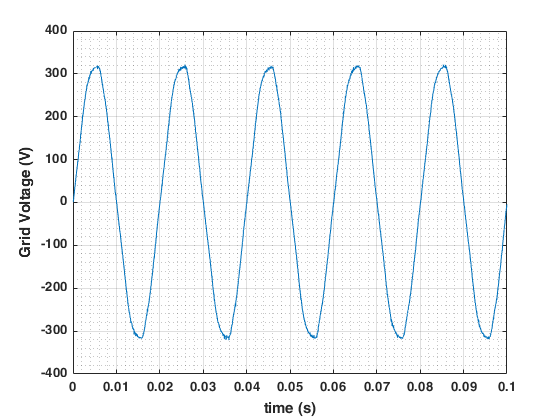

%%% FIRST RUN a.load_data.mlx;

measurement = meas11;

grid_voltage_real = measurement.V_ch1; 
time_vector = measurement.Timestamp;

plot(time_vector, grid_voltage_real);
xlabel("time (s)"); ylabel("Grid Voltage (V)");
grid on; grid minor;

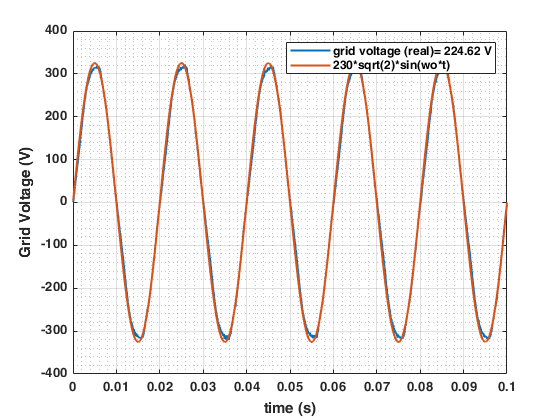


w0 = (50*2*pi());
grid_voltage_expected = 230*sqrt(2)*sin(time_vector.*w0);

plot(time_vector, grid_voltage_real, 'LineWidth', 1.5); 
hold on; plot(time_vector, grid_voltage_expected, 'LineWidth', 1.5); 
legend(strcat("grid voltage (real)= ", num2str(rms(grid_voltage_real), '%.2f'), " V"), "230*sqrt(2)*sin(wo*t)");
xlabel("time (s)"); ylabel("Grid Voltage (V)");
grid on; grid minor;

hold off;

## Spectrum Analysis

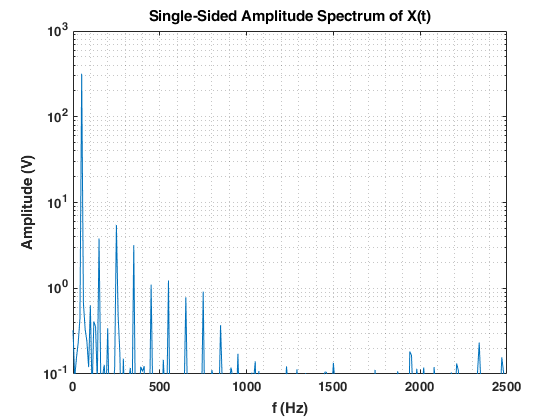

x = grid_voltage_real;
Fs = length(grid_voltage_real)*10;
L = length(x);
Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
semilogy(f,P1); grid minor;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('Amplitude (V)')
xlim([0 2500]);
ylim([1e-1 1e3]);

## Harmonic analysis

h_1= 1*5+1;  h_3 = 3*5+1;  h_5 = 5*5+1;
grid_voltage_expected = P1(h_1)*sin(time_vector.*w0);
grid_voltage_diff = grid_voltage_real-grid_voltage_expected;
grid_voltage_diff = grid_voltage_real-grid_voltage_expected;

%%%THD = VRMS_no_50Hz/VRMS_50Hz
THD_grid_voltage = rms(grid_voltage_diff)/(P1(h_1)/sqrt(2));
fprintf("Value of THD: 100 * (V diff)/(V h1) = %.2f %%", THD_grid_voltage * 100);

Value of THD: 100 * (V diff)/(V h1) = 3.70 %

fprintf("Value of 5th harmonic = %.2f %%", (P1(h_5)/(P1(h_1)))*100);

Value of 5th harmonic = 1.73 %

**IEEE Std 519**, “RECOMMENDED PRACTICES AND REQUIREMENTS FOR HARMONIC CONTROL IN ELECTRICAL POWER SYSTEMS”:

[https://edisciplinas.usp.br/pluginfile.php/1589263/mod_resource/content/1/IEE%20Std%20519-2014.pdf](https://edisciplinas.usp.br/pluginfile.php/1589263/mod_resource/content/1/IEE%20Std%20519-2014.pdf)

Low voltage Systems: max THD = 8% and max individual harmonic = 5%